# HW4

## Preprocessing

clear global

% Reading in the Excel file as a table then converting it into a matrix
mytable = readtable('project8_data.xlsx');
x = mytable{2:3,13:end};
x = transpose(x);

% 1st column: cumulative number of detected infections
V = x(:,1)

V =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


% 2nd column: Covid-19 related deaths reported in that specific county/city
Y = x(:,2)

Y =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Nmax = 236842; % Max population; from Population column
Tmax = 119;    % Number of days we will attempt to model
Tmaxnew = 40;  % Tmax cut in third
Vmin = 5;      % See below
tau0 = 7;      % Time between infection and full symptom onset
h = 0.01;      % Step size

% Sets used in omega set generation 
alphaSet = 0.05:0.01:0.2;
R0Set = 1.5:0.1:1.9;
deltaSet = 0.05:0.01:0.4;
NfracSet = 0.02:0.01:0.1;

% Norm used in error calculation
pSet = [1 2 inf];
pLen = length(pSet);

% Get the first day where at least Vmin were detected as infected
for i = 1:length(V)
    if V(i) >= Vmin
        break
    end
end
t0 = i

t0 = 52


% Preprocess rate of infections
I = zeros(Tmax+1,1); % note that I(t) represents the value of I at t+1
for t=0:Tmax
    I(t+1) = V(t+t0+tau0) - V(t+t0-tau0);
end
I

I =     17
    22
    26
    34
    35
    45
    52
    58
    68
    77



I0 = I(1)

I0 = 17

## Question 1

% Get parameters
% Function defined in generateParams1.m
[~, ~, ~, omega1] = generateParams1(alphaSet, R0Set, NfracSet, Nmax);

% gammas(alphaInd, betaInd, NInd, p) contains 
% gamma as calculated to minimize p-norm of residual
% of actual results as compared to euler model 
% with given parameters (alpha, beta, N)
% J(...) contains the minimized function value
[J1, gammas1] = SIR_euler_allParams(t0, Tmax, I0, Y, omega1, pSet);

alphas iterated over: 0.05, 0.06, 0.07, 0.08, 0.09, 0.10, 0.11, 0.12, 0.13, 0.14, 0.15, 0.16, 0.17, 0.18, 0.19, 0.20, 

[~, ~, ~, paramMinp] = SIR_euler_minParams(omega1, pSet, J1, gammas1)

## Question 2

[J2, gammas2] = SIR_euler_allParams(t0, Tmaxnew, I0, Y, omega1, pSet);

alphas iterated over: 0.05, 0.06, 0.07, 0.08, 0.09, 0.10, 0.11, 0.12, 0.13, 0.14, 0.15, 0.16, 0.17, 0.18, 0.19, 0.20, 


[~, ~, ~, paramMinp2] = SIR_euler_minParams(omega1, pSet, J2, gammas2)

For p = 1, the parameters which reduce the error are
alpha = 0.170, beta = 0.323, gamma = 0.005,N = 23684.2
with an error of 63.746773

For p = 2, the parameters which reduce the error are
alpha = 0.170, beta = 0.323, gamma = 0.004,N = 23684.2
with an error of 16.497747

For p = Inf, the parameters which reduce the error are
alpha = 0.160, beta = 0.304, gamma = 0.005,N = 23684.2
with an error of 6.622158



alphaMinInd2 = 12

betaMinInd2 = 5

NMinInd2 = 9

paramMinp2 = 3×4 cell array
    {[0.1700]}    {[0.3230]}    {[0.0046]}    {[2.3684e+04]}
    {[0.1700]}    {[0.3230]}    {[0.0042]}    {[2.3684e+04]}
    {[0.1600]}    {[0.3040]}    {[0.0047]}    {[2.3684e+04]}


Estimate if and when the infections would die down, i.e., when the number of infections would fall below Vmin = 5.

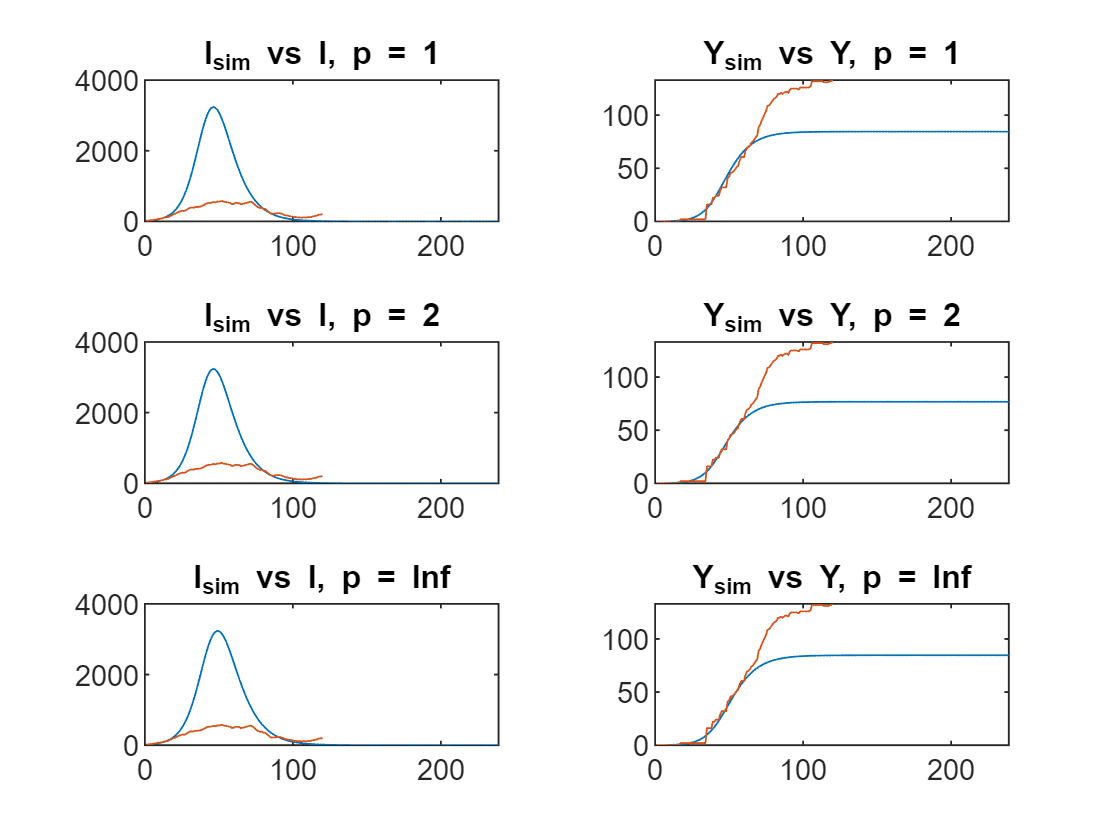

p = 1, predict first day below 5 infections after t0=52 is 126
p = 2, predict first day below 5 infections after t0=52 is 126


p = Inf, predict first day below 5 infections after t0=52 is 134


figure
tl = tiledlayout('flow');

for pInd = 1:pLen
    p = pSet(pInd);
    % Get minimum parameter values
    paramMin = paramMinp2(pInd,:);
    [alphaMin, betaMin, gammaMin, NMin] = paramMin{:};

    % Recalculated because it's not stored previously
    [Ssim, Isim, Rsim] = SIR_euler(I0, Tmax * 2, alphaMin, betaMin, NMin);

    % Compare Isim and I
    nexttile
    plot(Isim)
    hold on
    plot(I)
    hold off
    %legend(["predicted", "actual"])
    title(['I_{sim} vs I, p = ', num2str(p)])

    % Compare Y and Ysim = gamma * Rsim
    nexttile
    plot(gammaMin * Rsim)
    hold on
    plot(Y(t0:t0+Tmax))
    hold off
    %legend(["predicted", "actual"])
    title(['Y_{sim} vs Y, p = ', num2str(p)])    

    % Find value of Isim after index t0 below Vmin
    % TODO should I be looking at V instead? I don't know
    % how I would compare that with the output of the model...
    temp_mat = (Isim(t0+1:end)<=Vmin);
    %temp_mat(temp_mat == 0) = NaN;
    [~, min_idx] = max(temp_mat);

    fprintf("p = %d, predict first day below %d infections after t0=%d is %d\n", ...
        p, Vmin, t0, min_idx+t0)
    fprintf("")
end


fprintf("In reality, within the given data, I never goes below 5 after t0=%d.\n", t0)

In reality, within the given data, I never goes below 5 after t0=52.


## Question 3

% Get parameters
% Function defined in generateParams2.m
[~, ~, ~, omega2] = generateParams2(alphaSet, R0Set, deltaSet, NfracSet, Nmax);

% gammas(alphaInd, betaInd, deltaInd, NInd, p) contains 
% gamma as calculated to minimize p-norm of residual
% of actual results as compared to euler model 
% with given parameters (alpha, beta, delta, N)
% J(...) contains the minimized function value
[J3, gammas3] = SEIR_euler_allParams(t0, Tmax, I0, Y, omega2, pSet);

alphas iterated over: 0.05, 0.06, 0.07, 0.08, 0.09, 0.10, 0.11, 0.12, 0.13, 0.14, 0.15, 0.16, 0.17, 0.18, 0.19, 0.20, 

J = J(:,:,1,1,1) =

   1.0e+03 *

    1.5998    1.6524    1.7261    1.8073    1.8904
    1.6251    1.6927    1.7792    1.8681    1.9651
    1.6484    1.7289    1.8225    1.9200    2.0298
    1.6700    1.7599    1.8580    1.9648    2.0831
    1.6892    1.7858    1.8884    2.0036    2.1284
    1.7058    1.8074    1.9143    2.0360    2.1664
    1.7198    1.8256    1.9364    2.0626    2.1973
    1.7330    1.8410    1.9559    2.0854    2.2214
    1.7447    1.8540    1.9727    2.1045    2.2400
    1.7548    1.8650    1.9870    2.1206    2.2542
    1.7636    1.8749    1.9993    2.1339    2.2651
    1.7712    1.8834    2.0095    2.1446    2.2729
    1.7779    1.8907    2.0180    2.1532    2.2784
    1.7838    1.8969    2.0251    2.1602    2.2819
    1.7890    1.9026    2.0310    2.1655    2.2836
    1.7935    1.9075    2.0361    2.1694    2.2838


J(:,:,2,1,1) =

   1.0e+03 *

    1.6112    1.6855    1.7753    1.8671    1.9686
    1.6461    1.7377    1.8358    1.9429    2.0611
    1.6775    1.

gammas = gammas(:,:,1,1,1) =

    0.8802    0.8170    0.7428    0.6719    0.6081
    0.7645    0.6938    0.6195    0.5535    0.4950
    0.6727    0.6040    0.5335    0.4717    0.4175
    0.6101    0.5378    0.4705    0.4121    0.3615
    0.5621    0.4871    0.4226    0.3671    0.3195
    0.5200    0.4472    0.3850    0.3320    0.2891
    0.4854    0.4149    0.3548    0.3041    0.2614
    0.4576    0.3884    0.3301    0.2813    0.2405
    0.4340    0.3662    0.3096    0.2625    0.2234
    0.4138    0.3474    0.2923    0.2498    0.2091
    0.3965    0.3313    0.2775    0.2337    0.1970
    0.3815    0.3174    0.2648    0.2249    0.1867
    0.3683    0.3052    0.2537    0.2169    0.1778
    0.3566    0.2945    0.2440    0.2080    0.1701
    0.3463    0.2850    0.2354    0.2001    0.1633
    0.3370    0.2765    0.2277    0.1932    0.1573


gammas(:,:,2,1,1) =

    0.7838    0.7126    0.6372    0.5702    0.5107
    0.6699    0.5916    0.5217    0.4605    0.4070
    0.5829    0.5074    0.442

% Save results (so if I need to restart I don't lose the calculations)
% Commented so that I don't overwrite the results later
%writematrix(J3,"project1_q3_errors_all_p.txt")
%writematrix(gammas3,"project1_q3_gammas_all_p.txt")

[~, ~, ~, paramMinp3] = SEIR_euler_minParams(omega2, pSet, J3, gammas3)

For p = 1, the parameters which reduce the error are
alpha = 0.160, beta = 0.304, gamma = 0.037,N = 0.27
with an error of 346.946541

For p = 2, the parameters which reduce the error are
alpha = 0.200, beta = 0.380, gamma = 0.024,N = 0.25
with an error of 298.355784

For p = Inf, the parameters which reduce the error are
alpha = 0.190, beta = 0.361, gamma = 0.018,N = 0.31
with an error of 284.188991



alphaMinInd3 = 15

betaMinInd3 = 5

NMinInd3 = 27

paramMinp3 = 3×4 cell array
    {[0.1600]}    {[0.3040]}    {[0.0369]}    {[0.2700]}
    {[0.2000]}    {[0.3800]}    {[0.0243]}    {[0.2500]}
    {[0.1900]}    {[0.3610]}    {[0.0182]}    {[0.3100]}


## Question 4

[J4, gammas4] = SEIR_euler_allParams(t0, Tmaxnew, I0, Y, omega2, pSet);

alphas iterated over: 0.05, 0.06, 0.07, 0.08, 0.09, 0.10, 0.11, 0.12, 0.13, 0.14, 0.15, 0.16, 0.17, 0.18, 0.19, 0.20, 

% Save results (so if I need to restart I don't lose the calculations)
% Commented so that I don't overwrite the results later
%writematrix(J4,"project1_q4_errors_all_p.txt")
%writematrix(gammas4,"project1_q4_gammas_all_p.txt")

% Load matrix from file above
J4 = readmatrix("project1_q4_errors_all_p.txt")

J4 =   125.8844  125.6276  125.3689  125.1081  124.8452  125.4603  125.1712  124.8797  124.5852  124.2879  125.1282  124.8109  124.4894  124.1644  123.8259  124.8643  124.5205  124.1720  123.8084  123.4290  124.6506  124.2830  123.9044  123.5029  123.0946  124.4755  124.0859  123.6715  123.2448  122.8084  124.3304  123.9158  123.4737  123.0221  122.5612  124.2085  123.7672  123.3037  122.8304  122.3462  124.1057  123.6398  123.1567  122.6619  122.1556  124.0180  123.5300  123.0283  122.5141  121.9872
  126.0164  125.7217  125.4243  125.1237  124.8207  125.5340  125.2016  124.8652  124.5250  124.1810  125.1518  124.7850  124.4132  124.0363  123.6343  124.8429  124.4448  124.0401  123.6077  123.1651  124.5891  124.1619  123.7113  123.2423  122.7638  124.3777  123.9193  123.4291  122.9281  122.4160  124.1994  123.7047  123.1859  122.6550  122.1114  124.0476  123.5191  122.9741  122.4151  121.8418  123.9124  123.3579  122.7880  122.2030  121.6015  123.7926  123.2164  122.6233  122.0133  12

gammas4 = readmatrix("project1_q4_gammas_all_p.txt")

gammas4 =     0.0957    0.0944    0.0932    0.0920    0.0908    0.0896    0.0883    0.0870    0.0857    0.0845    0.0848    0.0833    0.0820    0.0807    0.0839    0.0807    0.0792    0.0778    0.0808    0.0795    0.0772    0.0758    0.0785    0.0771    0.0758    0.0743    0.0729    0.0754    0.0739    0.0726    0.0718    0.0742    0.0727    0.0713    0.0698    0.0696    0.0719    0.0704    0.0689    0.0674    0.0677    0.0699    0.0683    0.0668    0.0653    0.0660    0.0680    0.0665    0.0649    0.0634
    0.0837    0.0824    0.0811    0.0799    0.0786    0.0780    0.0767    0.0753    0.0740    0.0728    0.0734    0.0720    0.0706    0.0693    0.0719    0.0696    0.0682    0.0668    0.0692    0.0678    0.0664    0.0649    0.0672    0.0657    0.0644    0.0637    0.0657    0.0643    0.0628    0.0614    0.0614    0.0633    0.0618    0.0603    0.0589    0.0594    0.0611    0.0596    0.0581    0.0566    0.0607    0.0592    0.0577    0.0562    0.0547    0.0591    0.0575    0.0559    0.054

[~, ~, ~, ~, paramMinp4] = SEIR_euler_minParams(omega2, pSet, J4, gammas4)

For p = 1, the parameters which reduce the error are
alpha = 0.200, beta = 0.380, gamma = 0.011, delta = 0.400, N = 23684.2
with an error of 84.224266

For p = 2, the parameters which reduce the error are
alpha = 0.200, beta = 0.380, gamma = 0.010, delta = 0.400, N = 23684.2
with an error of 19.365021

For p = Inf, the parameters which reduce the error are
alpha = 0.200, beta = 0.380, gamma = 0.009, delta = 0.400, N = 23684.2
with an error of 7.144834



paramMinp4 = 3×5 cell array
    {[0.2000]}    {[0.3800]}    {[0.0108]}    {[0.4000]}    {[2.3684e+04]}
    {[0.2000]}    {[0.3800]}    {[0.0102]}    {[0.4000]}    {[2.3684e+04]}
    {[0.2000]}    {[0.3800]}    {[0.0091]}    {[0.4000]}    {[2.3684e+04]}


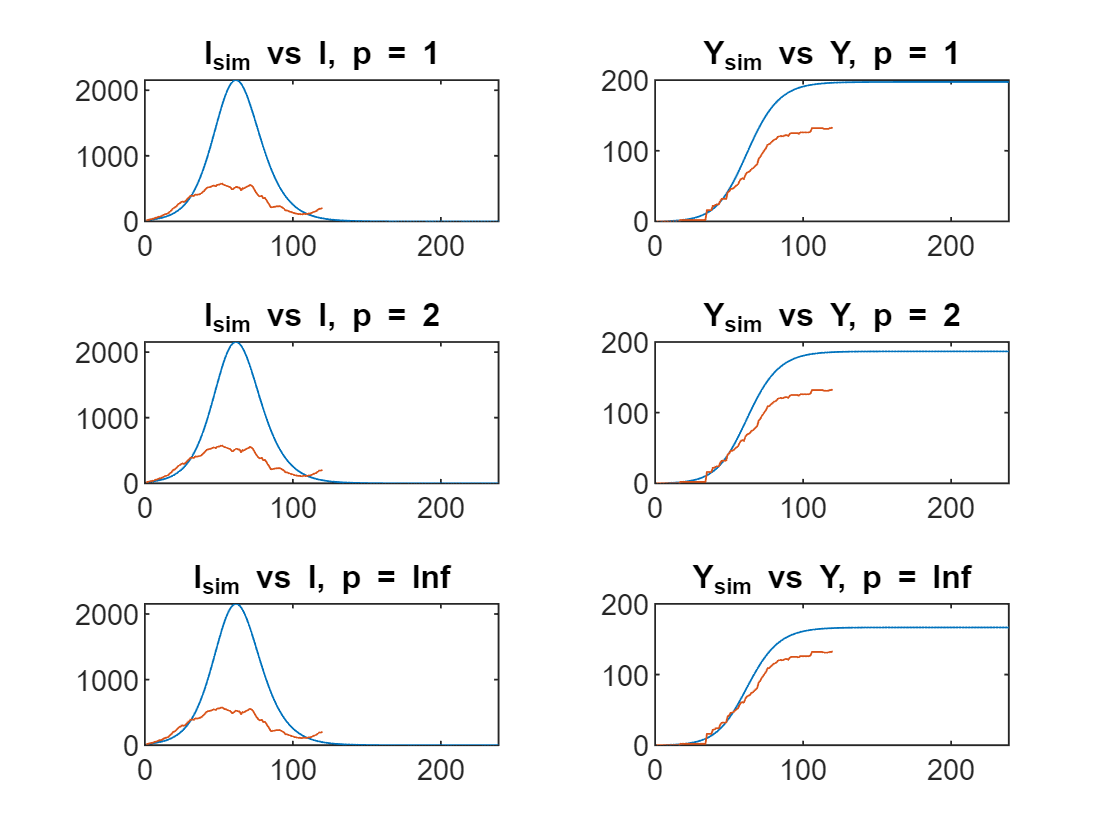

p = 1, predict first day below 5 infections after t0=52 is 146
p = 2, predict first day below 5 infections after t0=52 is 146


p = Inf, predict first day below 5 infections after t0=52 is 146


figure
tl = tiledlayout('flow');

for pInd = 1:pLen
    p = pSet(pInd);
    % Get minimum parameter values
    paramMin = paramMinp4(pInd,:);
    [alphaMin, betaMin, gammaMin, deltaMin, NMin] = paramMin{:};

    % Recalculated because it's not stored previously
    [Ssim, Esim, Isim, Rsim] = SEIR_euler(I0, Tmax * 2, alphaMin, betaMin, deltaMin, NMin);

    % Compare Isim and I
    nexttile
    plot(Isim)
    hold on
    plot(I)
    hold off
    %legend(["predicted", "actual"])
    title(['I_{sim} vs I, p = ', num2str(p)])

    % Compare Y and Ysim = gamma * Rsim
    nexttile
    plot(gammaMin * Rsim)
    hold on
    plot(Y(t0:t0+Tmax))
    hold off
    %legend(["predicted", "actual"])
    title(['Y_{sim} vs Y, p = ', num2str(p)])    

    % Find value of Isim after index t0 below Vmin
    % TODO should I be looking at V instead? I don't know
    % how I would compare that with the output of the model...
    temp_mat = (Isim(t0+1:end)<=Vmin);
    %temp_mat(temp_mat == 0) = NaN;
    [~, min_idx] = max(temp_mat);

    fprintf("p = %d, predict first day below %d infections after t0=%d is %d\n", ...
        p, Vmin, t0, min_idx+t0)
    fprintf("")
end


fprintf("In reality, within the given data, I never goes below 5 after t0=%d.\n", t0)

In reality, within the given data, I never goes below 5 after t0=52.
